# Actividad 3: Evaluación - Configuración 2

Daniel Ruán Aguilar - A01731921.

## Objetivo

Para esta actividad se debe obtener el vector de velocidades lineal y angular para un robot de 3 grados de libertad (GDL) del siguiente tipo :

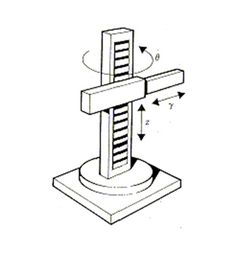

Imagen 1. Modelo

Aplicando los conocimientos vistos en la unidad de formación, se analiza este robot y se concluye que es de tipo cilíndrico, ya que tiene rotación en la base y las demás articulaciones son prismáticas, por lo que en su movimiento formará un cilindro, de ahí el nombre.

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

syms th1(t) l1(t) l2(t) l3(t) t 


Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición). En este caso, como son 3 articulaciones se colocan 3 elementos en el vector,  analizando el robot de abajo hacia arriba, primero tenemos una articulación rotacional por lo que se pone un cero, las siguientes prosmáticas y se ponen unos.

RP=[0 1 1];

Q= [th1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);


Creamos el vector de velocidades generalizadas sacando la derivada del vector de coordenadas articulares con la función diff, obtenemos la velocidad articular.

Qp= diff(Q, t);%diff() para derivadas con variable de referencia que no depende de otra: ejemplo el tiempo
%disp('Velocidades generalizadas');
%pretty (Qp);

Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, se coloca 2 porque indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);

Para determinar las matrices de rotación se pone un sistema de referencia en cada articulación empezando desde la base del robot, se coloca el eje z en paralelo con el movimiento de esa articulación y se rota en las demás articulaciones, con esta rotación se determina el ángulo que se sustituirá en las siguientes matrices, dependiendo de en qué eje rotó el sistema de coordenadas.

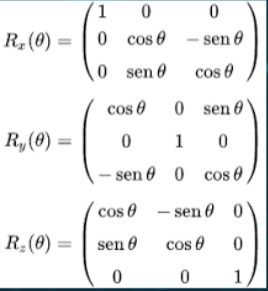

Imagen 2. Matrices de rotación

NOTA: si la rotación fue en la dirección de las manecillas del reloj el ángulo es negativo, de lo contrario es positivo.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0;l1];

Como es rotacional sobre su propio eje, no hay dezplazamiento y se sustiyute th1 en cada instante de tiempo en la matriz de rotación.

%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


En la segunda articulación si hay una translación, para cambiar el marco de referencia rota 90° sobre x, como gira a favor de las manecillas del reloj es un ángulo negativo.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0;l2];
%Matriz de rotación de la junta 2 respecto a 1.... -90º
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];


Para última por practicidad se deja la matriz identidad.

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; l3;0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

Se crea el vector de ceros y se inicializa tanto las matrices de transformación homogénea locales como las matrices de transformación homogénea globales.

Vector_Zeros= zeros(1, 3);

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los vectores de posición vistos desde el marco de referencia inercial con el número de grados de libertad.

PO(:,:,GDL)= P(:,:,GDL); 

Se Inicializan las matrices de rotación vistas desde el marco de referencia inercial con el número de grados de libertad

RO(:,:,GDL)= R(:,:,GDL); 


Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,   0   \
|                                     |
| sin(th1(t)),  cos(th1(t)), 0,   0   |
|                                     |
|      0,            0,      1, l1(t) |
|                                     |
\      0,            0,      0,   1   /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)),       0       \
|                                              |
| sin(th1(t)),  0,  cos(th1(t)),       0       |
|                                              |
|      0,      -1,       0,      l1(t) + l2(t) |
|                                              |
\      0,       0,       0,            1       /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)),           0           \
|                                                      |
| sin(th1(t)),  0,  cos(th1(t)),           0           |
|                                                      |
|      0,      -1,       0,      l1(t) + l2(t) - l3(t) |
|                                                      |
\      0,       0,       0,                1           /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente th1, l2 y l3, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.

%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);



Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

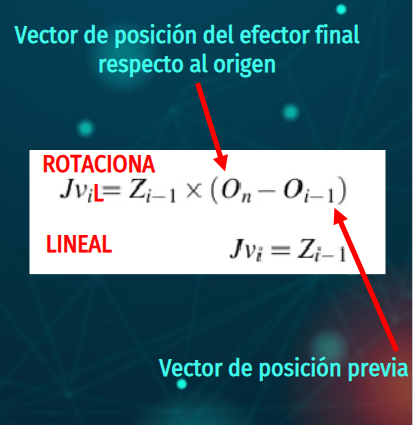

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Resultado de las operaciones hechas en el ciclo for para obtener el jacobiano lineal con los movimientos lineales en l2, l3 y th1.

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, 0, -sin(th1(t)) \
|                    |
| 0, 0,  cos(th1(t)) |
|                    |
\ 0, 1,       0      /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /



#### Resultados

Para finalmente desplegar los resultados con simplify y pretty para tener una visualización más entendible.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________             \
|    d                   |
| - -- l3(t) sin(th1(t)) |
|   dt                   |
|                        |
|  ________              |
|   d                    |
|  -- l3(t) cos(th1(t))  |
|  dt                    |
|                        |
|        ________        |
|         d              |
|        -- l2(t)        |
\        dt              /



Podemos observar que la velocidad lineal es correcta porque las dos articulaciones superiores son prismáticas (l2, l3), como se ve, no aparece th1. Vamos a tener movimiento de l2, unicamente en en **el eje z**, la articulación dos se colocó sobre el eje z y va a estar moviéndose sobre ese eje. Por otro lado la articulación tres tendrá desplazamiento en los eje "x" y "y", formando una especie de cilindro.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Podemos observar que la velocidad angular es correcta porque tenemos movimento rotacional únicamente en la primera articulación posicionando marco de referencia con el eje z sobre la artiucalción de actúa, las demás se muestran como cero porque no hay, la única velocidad que se muestra será sobre **el eje z**. Es la derivada de th1 porque recordamos que al derivar la posición, obtenemos la velocidad.